# Linear Control Design 2 - Fall 2022 - Exam Part I

## Introduction

The Part I of the Exam in Linear Control Design 2 (E22) consists of numerical exercises testing the acquisition of competences in the areas of analysis and design of control systems using modern control theory based on state space representation of system dynamics.

**The scoring of each problem is clearly stated.** 

It is the sole responsability of the student to guarantee that the solution delivered for evaluation can be run by the examiner without the need of contacting the student. All dependencies on files external to this Matlab Live Script must be checked and included in the final delivery. **If the examiner will not be able to execute the Matlab Live Script delivered as solution by the student, the Part I will be considered failed.** 

% Fill in your information
Exam = 'LCD2 E22'

Exam = 'LCD2 E22'

Student_Name = 'Student Name'

Student_Name = 'Student Name'

Student_Number = 'Student Number'

Student_Number = 'Student Number'

## Optimal output feedback control of a balance system

A balance system is a mechanical system in which the center of mass is balanced above a pivot point. A popular example of a balance system is the Segway Personal Transporter (shown in the figure below) where a motorized platform is used to stabilize the person standing on top of it. Balance systems are a generalization of a mass-spring-damper system to multi-degree-of-freedom, and the inverted pendulum on a cart (also shown in the figure below) is a good mechanical approximation of such systems.

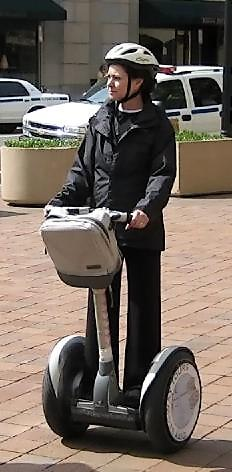            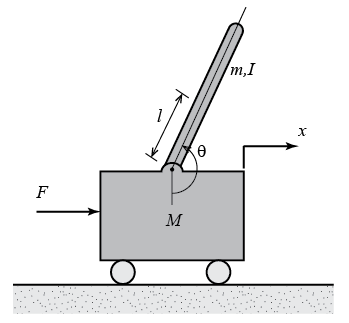

For this system the control input is the force $F$ that moves the cart in the longitudinal direction, and the measured output is the longitudinal position $x$ of the cart. The control objective is to keep the pendulum in its uprigth position ($\theta = \pi$rad) while moving the cart along the longitudinal direction. This is equivalent to the Segway Personal Transporter keeping its upright position while the rider leans forward to move along the ground. 

### Nonlinear model of the inverted pendulum on a cart

The nonlinear model describing the dynamical variations of the angular position of the pendulum $\theta$ and the linear position of the cart $x$ is described by the following nonlinear coupled second order differential equations

$(I + ml^2)\ddot{\theta} + c\dot{\theta} +mgl\sin\theta = -ml\ddot{x}\cos\theta  \\
(M+m)\ddot{x}+b\dot{x}+ml\ddot{\theta}\cos \theta-ml\dot{\theta}^2 \sin \theta = F \\
y = x$       (1)

where

- $M$is the mass of the cart

- $m$ is the mass of the pendulum

- $I$ is the inertia of the pendulum

- $b$ is the viscous friction coefficient of the cart

- $c$ is the viscous friction coefficient of the pendulum

- $l$ is the lenght of the pendulum

- $g$ is the gravitational constant 

The nonlinear model in Eq. (1) is implemented in the Simulink file InvertedPendulum_SimulinkYYYYC, where YYYYC refers to the Simulink version (2021b, 2021a, 2020b, 2020a, 2019b, 2019a, 2018b, 2018a, 2017b, 2017a). The numerical values for the model parameters are provided right below.

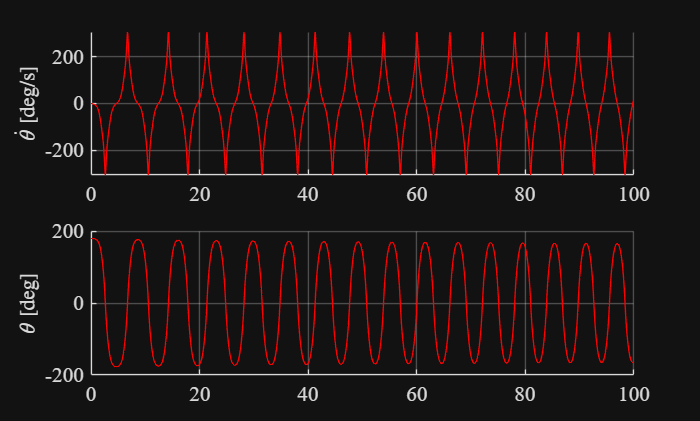

% Model paramters (RG)
% Prepare the workspace
clear all
clc
% System parameters
M = 10; % mass of trolley [kg]
m = 80; % mass of pendulum bob [kg]
b = 0.1; % friction coefficient trolley [kg/s]
c = 0.01; % friction coefficient pendulum [kg*m^2/s]
I = 100; % inertia of pendulum [kg*m^2]
g = 9.8; % gravity constant [m/s^2]
l = 1; % lenght of pendulum rod [m]

% Initial conditions for testing the Simulink model (RG)
theta_dot0 = 0; % pendulum angular velocity [rad/s]
theta0 = pi-0.01; % pendulum angular position [rad]
x_dot0 = 0; % trolley linear velocity [m/s]
x0 = 0; % trolley linear position [m]
F0 = 0; % linear force applied to the trolley [N]

% Test the provided inverted pendulum model (RG)
SIM_TIME = 100; % simulation time (can be changed as needed - if simulated for longer time, the pendulum returns to the downward position)
STEP_SIZE = 0.001; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
SIMULINK_FILENAME = 'InvertedPendulum_Simulink2021b';
time = (0:STEP_SIZE:SIM_TIME)';
F_ctrl = F0*ones(length(time),1);
sim(SIMULINK_FILENAME,SIM_TIME,[],[time F_ctrl])

% Plot the temporal behaviour of the quantities of interest (RG)
theta_dot = rad2deg(logsout.getElement('theta_dot').Values.Data);
theta = wrapTo180(rad2deg(logsout.getElement('theta').Values.Data)); % the pendulum angular position is wrapped between -180 and 180 degress
x_dot = logsout.getElement('x_dot').Values.Data;
x = logsout.getElement('x').Values.Data;

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time,theta_dot,'r','LineWidth',1)
ylabel('$\dot{\theta}$ [deg/s]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time,theta,'r','LineWidth', 1)
ylabel('$\theta$ [deg]','FontName','times','FontSize',16,'Interpreter','latex')

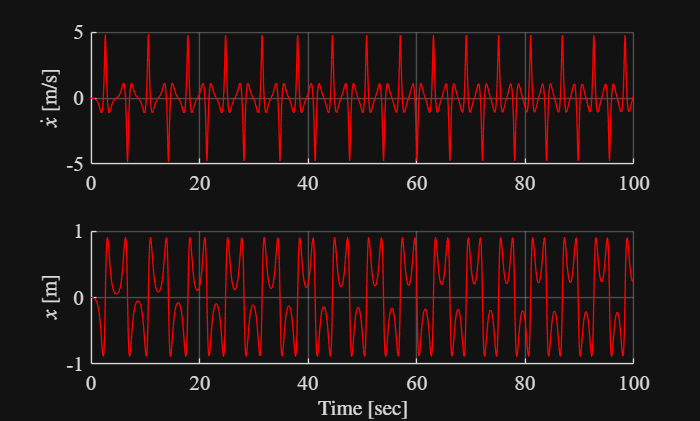

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time,x_dot,'r','LineWidth',1)
ylabel('$\dot{x}$ [m/s]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time,x,'r','LineWidth',1)
ylabel('$x$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

### Open-loop system analysis

**Problem 1 [2 points]** Based on the system dynamics described in Eq. (1), determine the system state vector, input, disturbance and output. Exploiting the Simulink model InvertedPendulum_SimulinkYYYYC linearize the system about the following operating point: $\theta = \pi \, \mathrm{rad}; \, \dot{\theta}= 0\, \mathrm{rad/s}; \, x = 0\,\mathrm{m}; \, \dot{x} = 0\, \mathrm{m/s}$.

% Your solution goes here

xss = [0;pi;0;0]; % stationary state, when nothing tilts or moves
yss = 0; % not needed for linmod()
uss = 0; % F = 0, no input
[A,B,C,D] = linmod(SIMULINK_FILENAME,xss,uss);

**Problem 2 [2 points]** Evaluate the internal and the external stability of system.

% Your solution goes here
lambda_ol = eig(A)

lambda_ol =          0
    2.6829
   -2.6837
   -0.0011


disp('One eigenvalue has positive real part => System is unstable')

One eigenvalue has positive real part => System is unstable


The system is not internally stable. Let's check for external stability:

[num, den] = ss2tf(A,B,C,D);
G = minreal(tf(num, den));
eigenvalues = pole(G)

eigenvalues =          0
   -2.6837
    2.6829
   -0.0011


disp('One pole has positive real part => System is not BIBO stable')

One pole has positive real part => System is not BIBO stable


It is not externally stable.

**Problem 3 [2 points]** Compute the step response of the system, and discuss the behaviour of the system state and output in the light of the stability analysis.

% Your solution goes here

When stepping on the input force the cart start moving with constant acceleration. Over time this will give rise to a change in position following a parabola (position is the second integration of acceleration).

In response to the step the pendulum position and velocity of the linear system will diverge to infinity because of the unstable eigenvalue. If the step is performed on the nonlinear system the response of the cart position is exactly the same, however the pendulum will start swinging around its hinging point since its position is physically bounded between 0 and 2*pi.

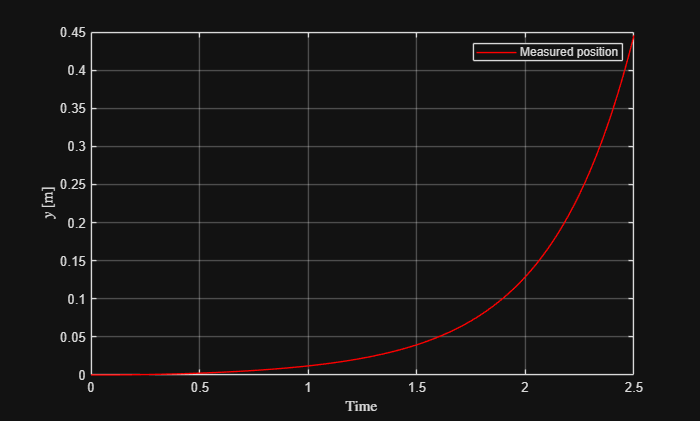

sys_original = ss(A,B,C,D);
figure()
tFinal = 2.5;
[y,t,x] = step(sys_original,tFinal);
plot(t, y, 'r')
ylabel('$y$ [m]', 'interpreter', 'latex')
xlabel('Time ', 'Interpreter','latex')
grid on
legend('Measured position')

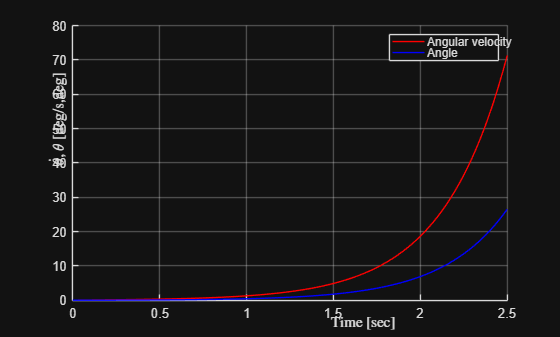

figure()
hold on
plot(t,rad2deg(x(:,1)),'r',t,rad2deg(x(:,2)),'b')
ylabel('$\dot{\theta},\theta$ [deg/s,deg]', 'Interpreter','latex')
xlabel('Time [sec]', 'Interpreter','latex')
legend('Angular velocity', 'Angle')
grid on

### Control system design for balance system

The main control objective is to maintain the pendulum in its upright position while the cart changes its position along the longitudinal direction, e.g. following a trajectory $x_{ref}(t)$. 

Closed-loop system requirements

The following closed-loop requirements should be fulfilled when the position of the cart changes of 1m

- The 1% settling time for $x$ is between 25 and 35 seconds;

- The pendulum angular position $\theta$ does not deviate more than $\pi/48 \, \mathrm{rad}$ ($\approx 4 \, \mathrm{deg}$) from the upright position;

- The steady state error is less than 3% for $x$

- The applied control force $F$ is within $\pm10\,\mathrm{N}$

- The pendulum angular position is kept at $\theta_{ref} = \pi \, \mathrm{rad}$.

**Problem 4 [6 points]** Under the assumption that the state is fully accessible design a discrete time optimal controller that meets the aforementioned requirements.

% Your solution goes here
% Controllability test
Mc = ctrb(A,B);

if rank(Mc) == size(A,1)
    disp('Open loop linear system is controllable')
else
    disp('Open loop linear system is not controllable')
end

Open loop linear system is controllable



% Sampling time
T_sett = 25; % selected settling time [s]
tau_sett = T_sett/5; % slowest time constant of closed loop system [s]
tau_ol = 1./abs(lambda_ol(abs(lambda_ol)>0));
Ts_max = min([tau_sett min(tau_ol)]./10); % maximum sampling time [s]
Ts = 0.01; % 10x smaller than settling time req

[F,G] = c2d(A,B,Ts);
R = 50;
Q = diag([100 1/(pi/48)^2 100 1/(0.03)^2]);
[K_opt,S,lambda_cl_dt] = dlqr(F,G,Q*Ts,R*Ts);

lambda_cl_dt = abs(lambda_cl_dt) % discrete time / Z-domain

lambda_cl_dt =     0.9984
    0.9984
    0.9736
    0.9735


All eigenvalues are <1, so the new system is stable.

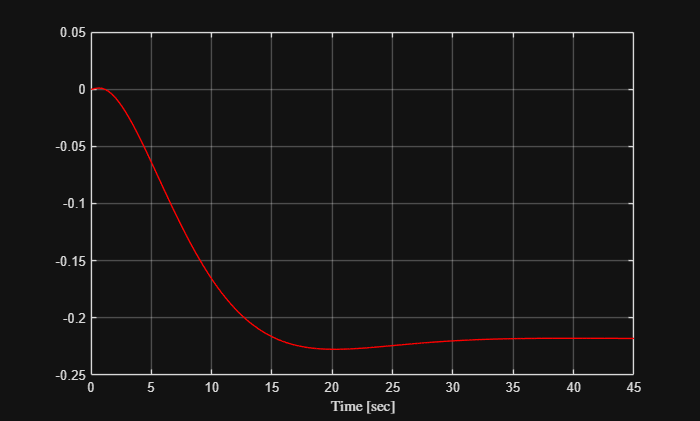

sys_discrete = ss(F-G*K_opt,G,C,D,Ts);
figure()
tFinal = 45;
[y,t,x] = step(sys_discrete,tFinal);
plot(t, y, 'r')
xlabel('Time [sec]', 'Interpreter','latex')
grid on

From Eq. (4.5) $A_K =A-\textrm{BK}$, in discrete $A_K =F-\textrm{GK}$

From slides $y_{\textrm{des}} =C{\left(-A_K \right)}^{-1} \textrm{BNr}$    $\Leftrightarrow$    $y_{\textrm{des}} {\left(C{\left(-A_K \right)}^{-1} B\right)}^{-1} =\textrm{Nr}$

Inserting $A_K$: $y_{\textrm{des}} {\left(C{\left(F-\textrm{GK}\right)}^{-1} G\right)}^{-1} =\textrm{Nr}$

So to get $y_{\textrm{des}} =r$ we have ${\left(C{\left(F-\textrm{GK}\right)}^{-1} G\right)}^{-1} =N$

No clue why we subtract identity matrix.

I think N is just the opposite of the whole closed loop system, so we just get $y_{\textrm{des}} {\textrm{sys}}_{\textrm{cl}} =\textrm{Nr}$. If $N={{\textrm{sys}}_{\textrm{cl}} }^{-1}$, we would just get $y_{\textrm{des}} =r$.

N = inv(C*inv(eye(4)-(F-G*K_opt))*G);
sys_cl_dt = ss(F-G*K_opt,G*N,C,D,Ts);
% Simulate closed-loop step response
x_ref0 = 1; % desired x of 1 meter
x_ref = x_ref0*(ones(length(time(1:Ts/STEP_SIZE:end)),1));
[y,t,x_lin] = lsim(sys_cl_dt,x_ref,time(1:Ts/STEP_SIZE:end));
% F_ctrl_lin = -K_opt*(x_lin'-ref);
F_ctrl_lin = -K_opt*x_lin' + N*x_ref'; % have have u = -Kx + Nr, which is the input - Force

x_lin is the simulation of the four states $\left\lbrack \dot{\theta} ,\theta ,\dot{x} ,x\right\rbrack$

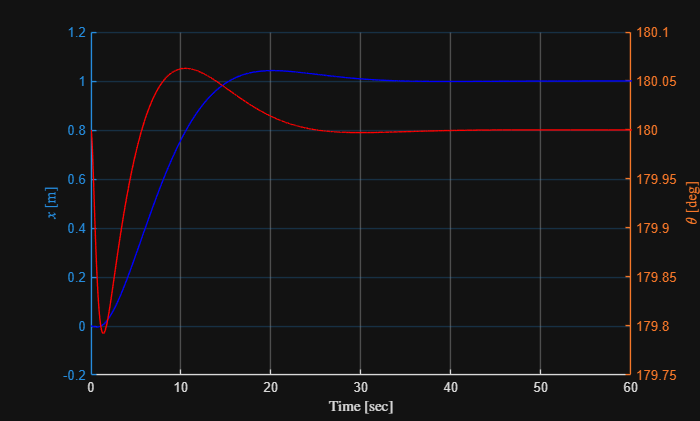

% Plotting the output (distance) and check for upright stability (angle).
% We want to check the stability (theta) of the system and reference
% tracking (x)
figure()
hold on
% manipulate left axis
yyaxis left
plot(t,y,'b')
ylabel('$x$ [m]','Interpreter','latex')
% manipulate the right axis
yyaxis right
plot(t,rad2deg(x_lin(:,2)+pi),'r')
ylabel('$\theta$ [deg]','Interpreter','latex')
% define x-axis
xlabel('Time [sec]','Interpreter','latex')
xlim([0,60])
grid on

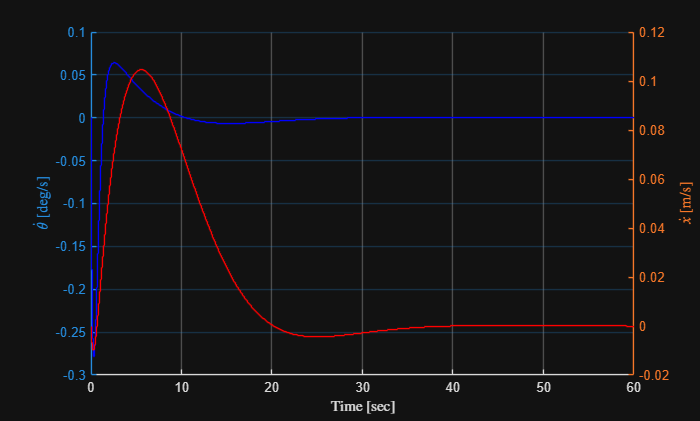

figure()
hold on
% Left y-axis - ,angular velocity, theta_dot
yyaxis left
stairs(t,rad2deg(x_lin(:,1)),'b')
ylabel('$\dot{\theta}$ [deg/s]','Interpreter','latex')
% Right y-axis - velocity, x_dot
yyaxis right
stairs(t,x_lin(:,3),'r')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
% X-axis
xlabel('Time [sec]','Interpreter','latex')
xlim([0,60])
grid on

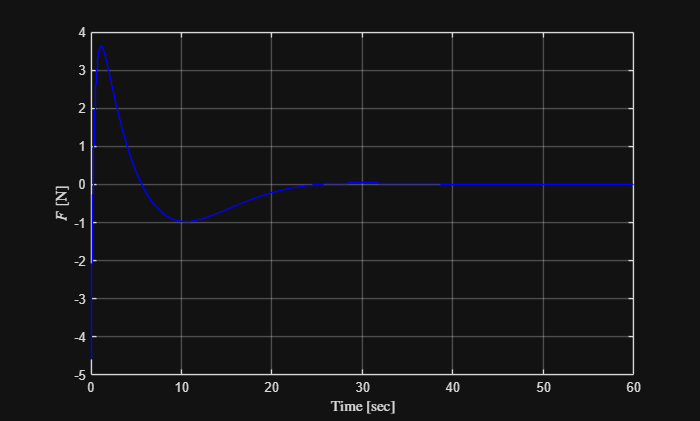

% Finally we plot the input force
figure()
stairs(t,F_ctrl_lin,'b')
ylabel('$F$ [N]','Interpreter','latex')
xlabel('Time [sec]','Interpreter','latex')
xlim([0,60])
grid on

**Problem 5 [2 points]** Implement the discrete time optimal controller in the Simulink model of the nonlinear system, and evalute the closed-loop system performance against the given requirements, when the sytem is subject to a step change in the reference cart position of $x_{ref} = 1 \, \mathrm{m}$.

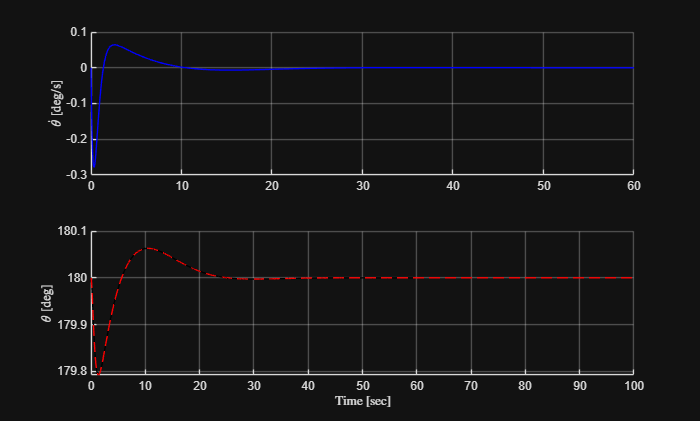

% Your solution goes here
% Test the closed-loop nonlinear system
SIM_TIME = 60; % simulation time (can be changed as needed)
STEP_SIZE = 0.001; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
theta0 = pi;
SIMULINK_FILENAME = 'InvertedPendulum_DLQR_Simulink2020b';
sim(SIMULINK_FILENAME,SIM_TIME,[])

% Get the outputs of the simulink model
time = logsout.getElement('theta_dot').Values.Time;
theta_dot = rad2deg(logsout.getElement('theta_dot').Values.Data);
theta = rad2deg(logsout.getElement('theta').Values.Data); % the pendulum angular position is wrapped between -180 and 180 degress
x_dot = logsout.getElement('x_dot').Values.Data;
x = logsout.getElement('x').Values.Data;
time_dt = logsout.getElement('F').Values.Time;
F_ctrl = logsout.getElement('F').Values.Data;

% Plots
figure()
h7 = subplot(2,1,1); % prof uses this extra -> set(h7,'FontName','times','FontSize',16)
hold on, grid on
plot(time,theta_dot,'b')
ylabel('$\dot{\theta}$ [deg/s]','Interpreter','latex')
h8 = subplot(2,1,2);
hold on, grid on
plot(time,theta,'k',t,rad2deg(x_lin(:,2)+pi),'--r')
ylabel('$\theta$ [deg]','Interpreter','latex')
xlabel('Time [sec]','Interpreter','latex')

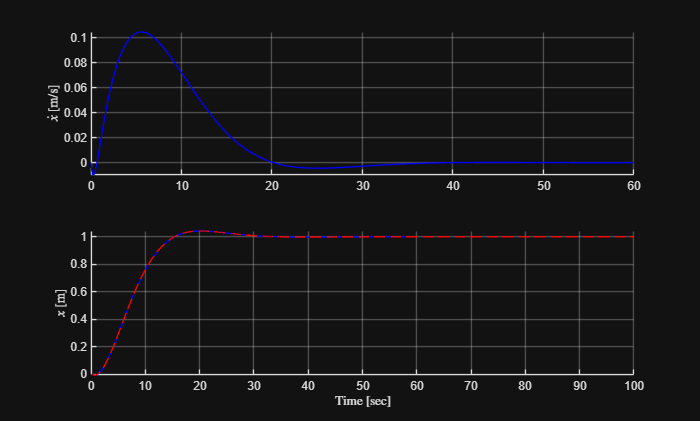

figure()
h9 = subplot(2,1,1);
hold on, grid on
plot(time,x_dot,'b')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
h10 = subplot(2,1,2);
hold on, grid on
plot(time,x,'b',t,x_lin(:,4),'--r')
ylabel('$x$ [m]','Interpreter','latex')
xlabel('Time [sec]','Interpreter','latex')

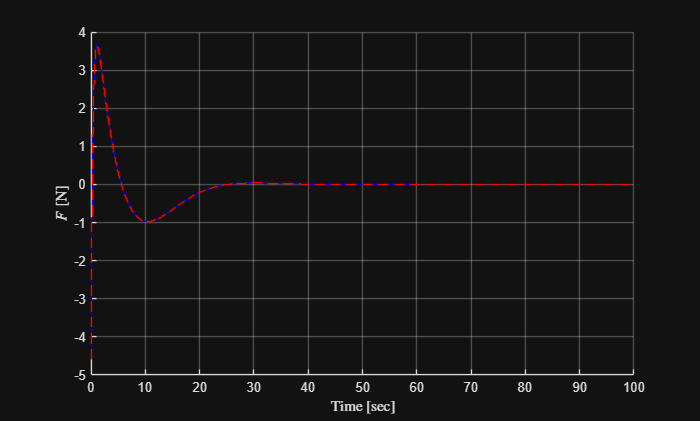

figure()
hold on, grid on
stairs(time_dt,F_ctrl,'b')
stairs(t,F_ctrl_lin,'--r')
ylabel('$F$ [N]','Interpreter','latex')
xlabel('Time [sec]','Interpreter','latex')

### State estimation for output feedback control

In order to implement an output feedback controller, the state vector must be estimated based on the available measurement of the cart position $x$. In the last part of the exercise, we assume the following measurement model

$y_1 = x + v_1$                            (2)

where $v_1$ is zero mean white noise. The noise amplitude is $\pm 0.005\, \mathrm{m}$. 

**Problem 6 [6 points]** Design a discrete time Kalman filter to estimate the state vector.

% Your solution goes here
% Observability test
Mo = obsv(A,C);

if rank(Mo) == size(A,1)
    disp('Open loop linear system is observable')
else
    disp('Open loop linear system is not observable')
end

Open loop linear system is observable


% V1 = diag([0.00001 0.000001 0.00001 0.000001]); % process noise uncertainty is low across all states since the linear model is a good approximation of the nonlinear model at the stationary state
% Bv = diag([A(1,1) 1 A(3,3) 1]); % process noise enters the system in the feedback loop of the states theta_dot and x_dot
% Qd = 0.00001*Ts;
% noise_ampl = 0.005;
% R = (noise_ampl/3)^2;
% Rd = R/Ts;
% sys_kf = ss(F, G, C, D, Ts);
% 
% [kalmf,L,P] = kalman(sys_kf,Qd,Rd)
% Define noise covariance
V1 = diag([0.00001 0.000001 0.00001 0.000001]);
Bv = diag([A(1,1) 1 A(3,3) 1]);
Q = Bv * V1 * Bv' * Ts;
noise_ampl = 0.005;
V2 = (noise_ampl / 3)^2;
R = V2 / Ts;

% Find L using dlqe()
F_KF = F;
G_KF = G;
Gv_KF = eye(4);
C_KF = C;
[L_KF,P,Z,lambda_ee_dt] = dlqe(F_KF, Gv_KF, C_KF, Q, R)

L_KF =     0.2022
    0.0756
    0.1796
    0.0593


P = 1.0e-03 *

    0.2293    0.0861    0.2037    0.0597
    0.0861    0.0325    0.0765    0.0223
    0.2037    0.0765    0.1809    0.0530
    0.0597    0.0223    0.0530    0.0175


Z = 1.0e-03 *

    0.2172    0.0816    0.1930    0.0562
    0.0816    0.0308    0.0725    0.0210
    0.1930    0.0725    0.1714    0.0499
    0.0562    0.0210    0.0499    0.0165


lambda_ee_dt =     1.0000
    0.9916
    0.9768
    0.9712


% Find L using kalman(), with augmented system
num_states = size(F,1);
num_outputs = size(G,2);
G_kf = [G eye(num_states)];
D_kf = zeros(size(C,1), num_states + num_outputs);
sys_kf = ss(F_KF, G_kf, C_KF, D_kf, Ts);
[kalmf, L_kalman, P] = kalman(sys_kf, Q, R)


kalmf =
 
  A = 
               x1_e        x2_e        x3_e        x4_e
   x1_e           1     0.07201  -8.164e-06     -0.2077
   x2_e        0.01           1  -4.082e-08    -0.07763
   x3_e   0.0003192     0.06401           1     -0.1845
   x4_e   1.063e-06     0.00032        0.01      0.9389
 
  B = 
                u1         y1
   x1_e  8.164e-05     0.2077
   x2_e  4.082e-07    0.07763
   x3_e  0.0001837     0.1845
   x4_e  9.184e-07    0.06114
 
  C = 
             x1_e      x2_e      x3_e      x4_e
   y1_e         0         0         0    0.9407
   x1_e         1         0         0   -0.2022
   x2_e         0         1         0  -0.07558
   x3_e         0         0         1   -0.1796
   x4_e         0         0         0    0.9407
 
  D = 
              u1       y1
   y1_e        0  0.05932
   x1_e        0   0.2022
   x2_e        0  0.07558
   x3_e        0   0.1796
   x4_e        0  0.05932
 
Input groups:              
       Name        Channels
    KnownInput        1

L_kalman =     0.2077
    0.0776
    0.1845
    0.0611


P = 1.0e-03 *

    0.2293    0.0861    0.2037    0.0597
    0.0861    0.0325    0.0765    0.0223
    0.2037    0.0765    0.1809    0.0530
    0.0597    0.0223    0.0530    0.0175


**Problem 7 [2 points]** Implement the discrete time Kalman filter in the Simulink diagram of the closed-loop system and assess its estimation performance when a step change in the position of the cart of $x_{ref} = 1 \, \mathrm{m}$ takes place.

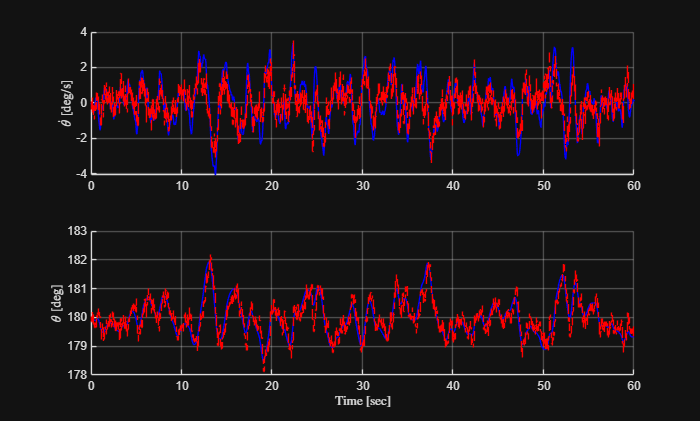

L_KF = L_kalman;
% Your solution goes here
x0_hat = zeros(4,1);

% Test the closed-loop output feedback optimal controller on the nonlinear system
SIM_TIME = 60; % simulation time (can be changed as needed)
STEP_SIZE = 0.0001; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
SIMULINK_FILENAME = 'InvertedPendulum_DLQG_Simulink2020b';
sim(SIMULINK_FILENAME,SIM_TIME,[])

% Plot the temporal behaviour of the quantities of interest 
time = logsout.getElement('theta_dot').Values.Time;
theta_dot = rad2deg(logsout.getElement('theta_dot').Values.Data);
theta = rad2deg(logsout.getElement('theta').Values.Data); % the pendulum angular position is wrapped between -180 and 180 degress
x_dot = logsout.getElement('x_dot').Values.Data;
x = logsout.getElement('x').Values.Data;
time_dt = logsout.getElement('F').Values.Time;
F_ctrl = logsout.getElement('F').Values.Data;
x_hat = logsout.getElement('x_hat').Values.Data+xss';
ym = logsout.getElement('ym').Values.Data;

figure()
subplot(2,1,1);
hold on, grid on
plot(time,theta_dot,'b')
stairs(time_dt,rad2deg(x_hat(:,1)),'--r')
ylabel('$\dot{\theta}$ [deg/s]','Interpreter','latex')
subplot(2,1,2);
hold on, grid on
plot(time,theta,'b')
stairs(time_dt,rad2deg(x_hat(:,2)),'--r')
ylabel('$\theta$ [deg]','Interpreter','latex')
xlabel('Time [sec]','Interpreter','latex')

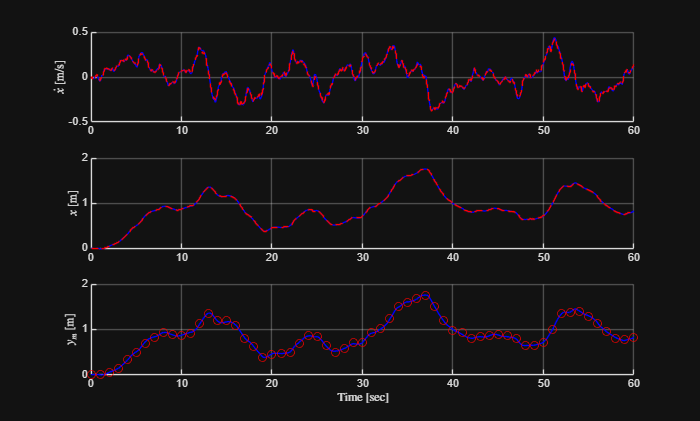

figure()
subplot(3,1,1);
hold on, grid on
plot(time,x_dot,'b')
stairs(time_dt,x_hat(:,3),'--r')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
subplot(3,1,2);
hold on, grid on
plot(time,x,'b')
stairs(time_dt,x_hat(:,4),'--r')
ylabel('$x$ [m]','Interpreter','latex')
subplot(3,1,3);
hold on, grid on
plot(time,x,'b')
plot(time_dt(1:100:end),ym(1:100:end),'or')
ylabel('$y_m$ [m]','Interpreter','latex')
xlabel('Time [sec]','Interpreter','latex')

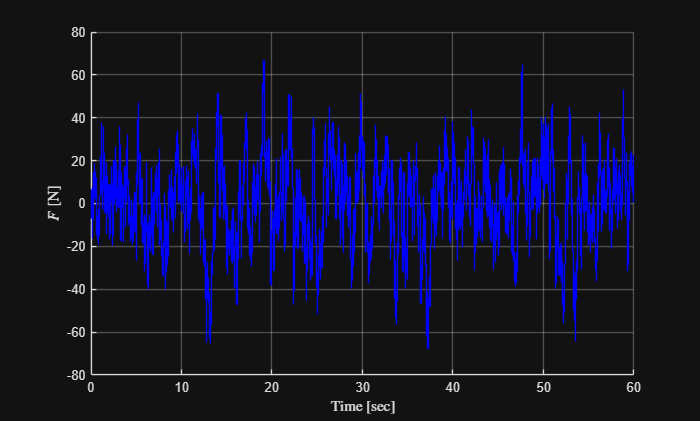

figure()
hold on, grid on
stairs(time_dt,F_ctrl,'b')
ylabel('$F$ [N]','Interpreter','latex')
xlabel('Time [sec]','Interpreter','latex')